duration = 1

duration = 1

steps    = 10000

steps = 10000

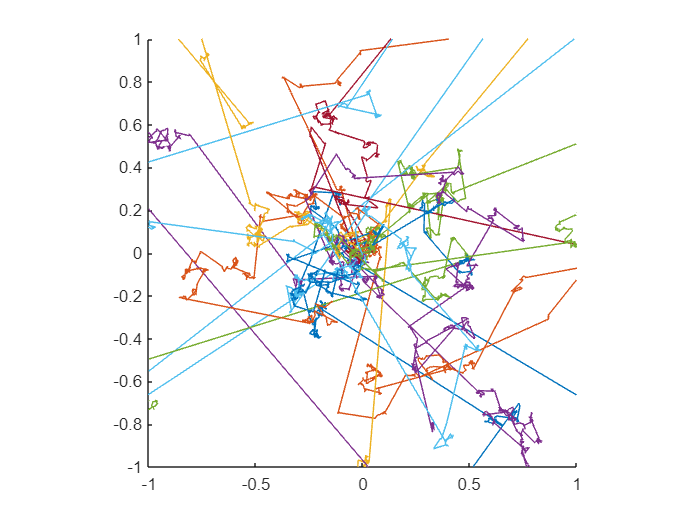


timestep = duration/steps;

clf
hold on
for i = 1:20
    thetas   = unifrnd(0, 2*pi, steps, 1);
    delta_Xs = timestep*sqrt(1./(1 - unifrnd(0, 1, steps, 1)).^2 - 1).*[cos(thetas), sin(thetas)];
    Xs       = zeros(steps + 1, 2);
    for step = 1:steps
        Xs(step + 1, :) = Xs(step, :) + delta_Xs(step, :);
    end
    
    plot(Xs(:, 1), Xs(:, 2))
end
hold off

axis equal
xlim([- 1, 1])
ylim([- 1, 1])